# Optimization of PID parameters for robot control position

#### New Version

## Open-loop response: Plant

% Initial data
t_max = 5

% Create plant
K=13.86;
T=0.0002648;
plant = tf(K,[T 1 0]);

% figure("Name","Open-loop step response for system");
% step(plant,0:0.05:t_max);


## Closed-loop respuesta: Motor 1

Iteration 5: Best=0.4417, Worst=0.5152, Global=9.6250
Iteration 10: Best=0.4238, Worst=0.4708, Global=9.0276
Iteration 15: Best=0.3886, Worst=0.4251, Global=8.1651
Iteration 20: Best=0.3732, Worst=0.4010, Global=7.8424


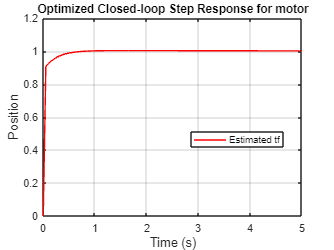

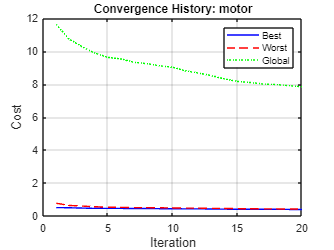

% Differential Evolution initial parameters
config = struct();
config.populationSize = 20;
config.maxIterations = 20;
config.F = 0.7;
config.CR = 0.5;
config.maxPIDValue = 1;% At initialization

% PID Optimization
optimizer = PIDOptimizer(plant, config,": motor 1");
Solutionv2_1 = optimizer.optimize();


% Display results
fprintf('\Optimization results:\n');
fprintf('Kp: %.4f\n', Solutionv2_1.bestmem(1));

Kp: 2.6386


fprintf('Ki: %.4f\n', Solutionv2_1.bestmem(2));

Ki: 0.4813


fprintf('Kd: %.4f\n', Solutionv2_1.bestmem(3));

Kd: 0.5500


fprintf('Final Error: %.4f\n', Solutionv2_1.error);

Final Error: 0.3732



% Results
% Kp: 2.6386
% Ki: 0.4813
% Kd: 0.5500
% Final Error: 0.3732


% figure('Name', 'Convergence History for PID optimization');
% plot(1:20, Solutionv2_1.CONV.MIN, 'b-', 'LineWidth', 2);
% hold on;
% plot(1:20, Solutionv2_1.CONV.MAX, 'r--', 'LineWidth', 2);
% plot(1:20, Solutionv2_1.CONV.GLOBAL, 'g:', 'LineWidth', 2);
% xlabel('Iteration', 'FontSize', 12);
% ylabel('Cost', 'FontSize', 12);
% title('Convergence History: motor 1');
% legend('Best', 'Worst', 'Global', 'Location', 'NorthEast');
% grid on;
% hold off;

## Motor 2